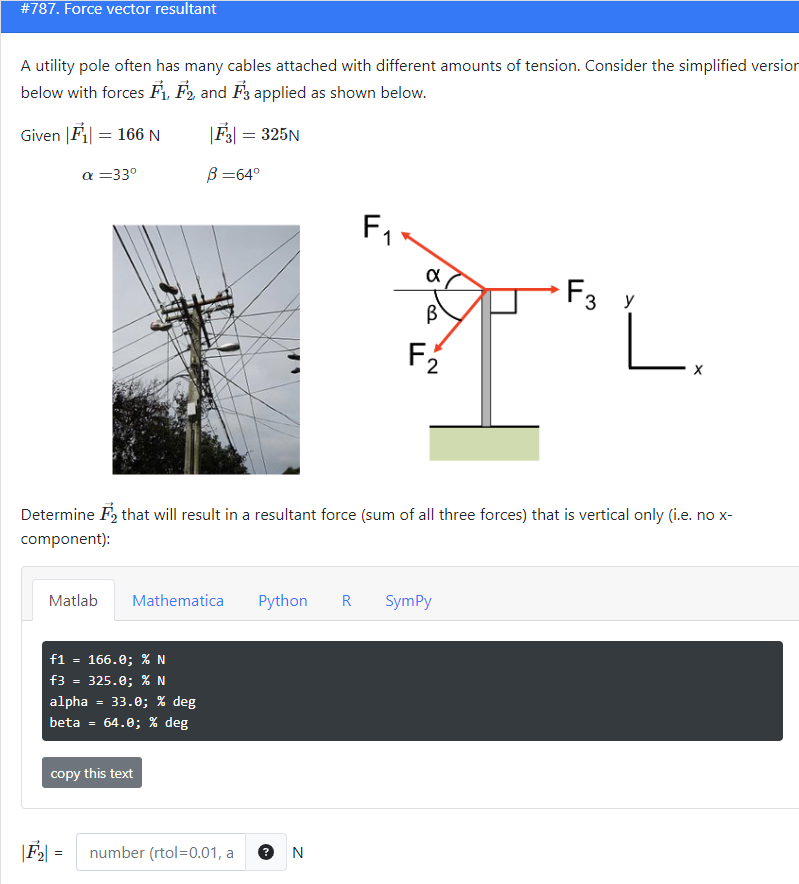

%% #787. Force vector resultant

f1 = 166.0; % N
f3 = 325.0; % N
alpha = 33.0; % deg
beta = 64.0; % deg

syms f2

ff1 = f1*[-cosd(alpha),sind(alpha)];
ff3 = [f3,0];
eqn1 = ff1(1) + ff3(1) + f2*-cosd(beta) == 0;
[f2] = vpasolve(eqn1,[f2]);
f2

$$f2 = 423.7977044836121170013398978255$$

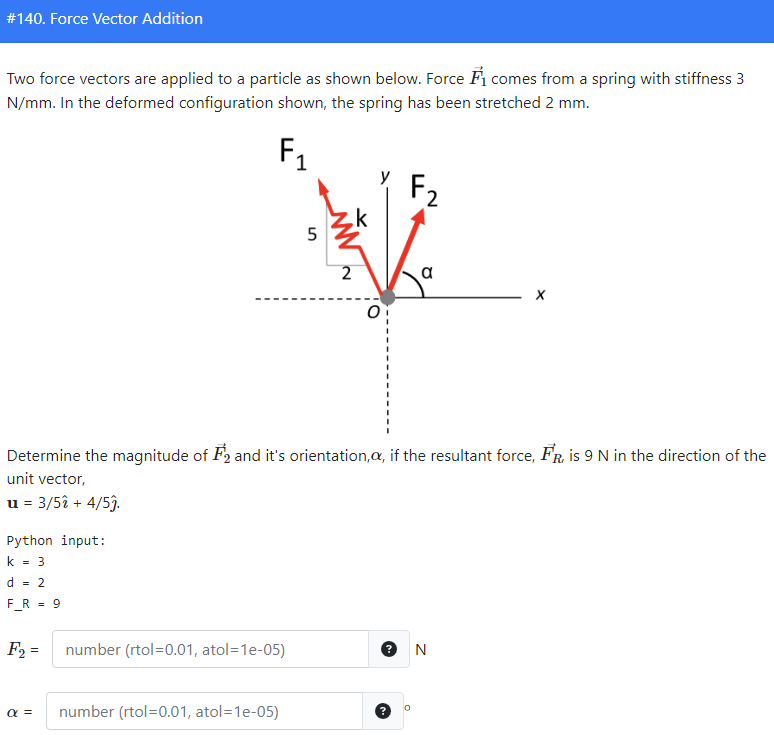

%% #140. Force Vector Addition


k = 3;
d = 2;
F_R = 9;

syms alpha f2
unitf1 = [-2,5];
unitf1 = unitf1/norm(unitf1);

ff1 = unitf1*k*d;

ff2 = f2*[cosd(alpha),sind(alpha)];

eqn1 = ff1 + ff2 == F_R*[3/5,4/5];
[f2,alpha] = vpasolve(eqn1,[f2,alpha])

$$f2 = 7.8003672820745765563600155261346$$

$$alpha = 12.055216795303219385211624105433$$

ans = -1.6499

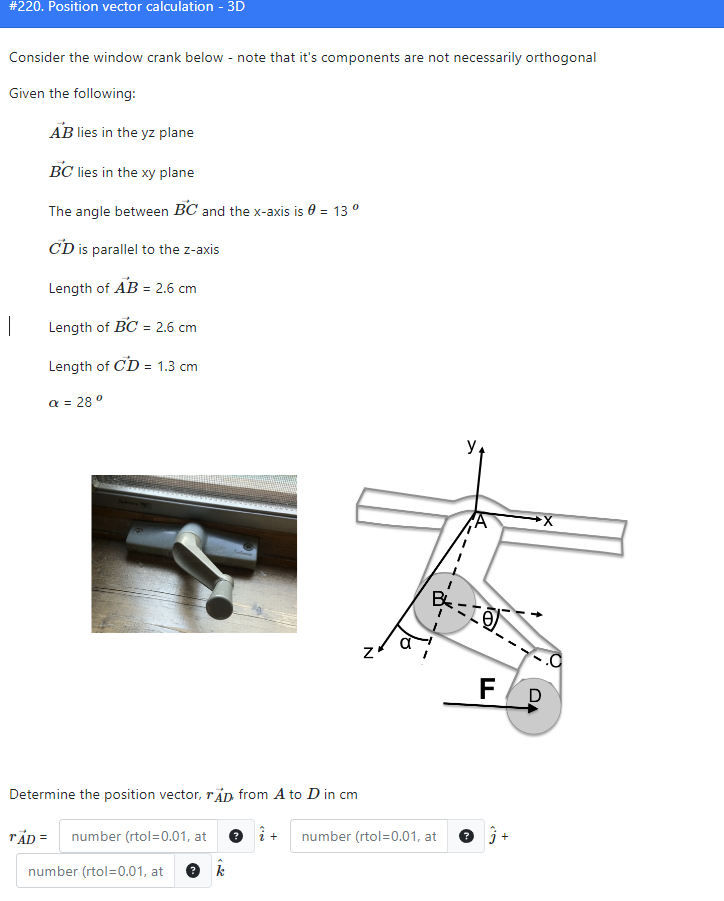

% #220. Position vector calculation - 3D
theta = 13;
ab = 2.6;
bc = 2.6;
cd = 1.3;
alpha = 28;

ab = ab*[0,-sind(alpha),cosd(alpha)];
bc = bc*[cosd(theta),-sind(theta),0];
cd = cd*[0,0,1];

ad = ab + bc + cd

ad =     2.5334   -1.8055    3.5957


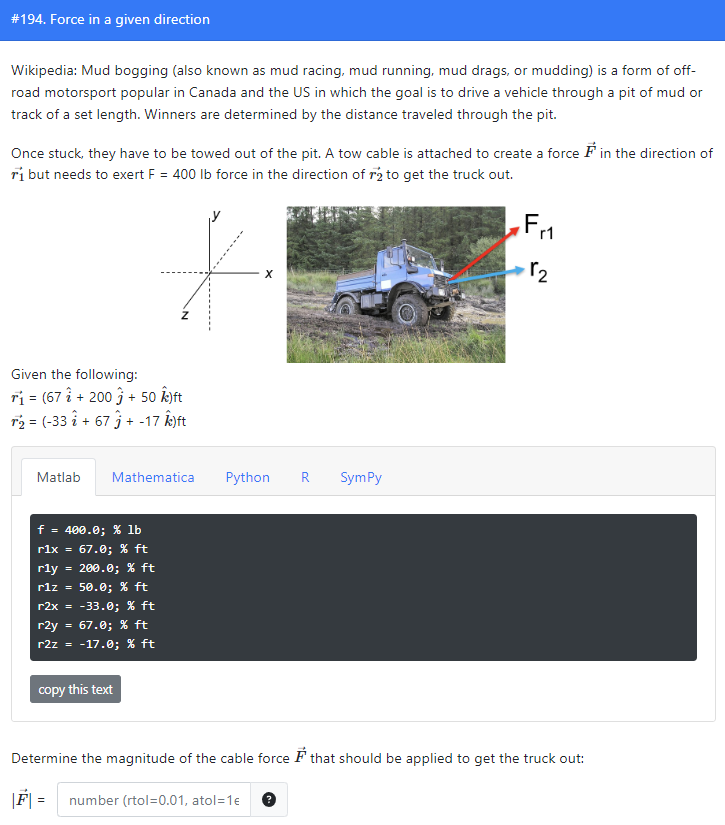

% #194. Force in a given direction
% F1 在r2 方向的投影应该是f
f = 400.0; % lb
r1x = 67.0; % ft
r1y = 200.0; % ft
r1z = 50.0; % ft
r2x = -33.0; % ft
r2y = 67.0; % ft
r2z = -17.0; % ft

r1 = [r1x,r1y,r1z];
r1 = r1/norm(r1);
r2 = [r2x,r2y,r2z];

syms fr;
fr1 = fr*r1

$$fr1 = \left(\begin{array}{ccc} \frac{67\,\sqrt{5221}\,\mathrm{fr}}{15663} & \frac{200\,\sqrt{5221}\,\mathrm{fr}}{15663} & \frac{50\,\sqrt{5221}\,\mathrm{fr}}{15663} \end{array}\right)$$

eqn1 = dot(fr1,r2)/norm(r2) ==f;
fr = vpasolve(eqn1,fr)

$$fr = 642.37347760209644163167654491351$$

%% traffic light HW3B 

x_a = 0;
y_a = 0;
z_a = 0;
x_b = 0;
y_b = 10.45 ;
z_b = 0 ;
x_c = 3.35 ;
y_c = 10.45;
z_c = 0;
x_d = 3.35 ;
y_d = 10.45;
z_d = 3;
x_e = 3.35 ;
y_e = 10.45 ;
z_e = -2.1;
m1= 2.4;
m2= 4.5;
m3= 1.1;

a = [x_a,y_a,z_a];
b = [x_b,y_b,z_b];
c = [x_c,y_c,z_c];
d = [x_d,y_d,z_d];
e = [x_e,y_e,z_e];

mm1 = [0,-m1,0] * 9.81;
mm2 = [0,-m2,0] * 9.81;
mm3 = [0,-m3,0] * 9.81;

rf = -(mm1+mm2+mm3);
rm = cross(d,mm1) + cross(c,mm2) + cross(e,mm3);
rm = -rm

rm =   -47.9709         0  262.9080


%% HW2B A 3D Resultant Problem England Soldier
% 注意单位
alpha = 85;
t = 700;
a = 350/100;
b = 170/100;
c = 530/100;
d = 390/100;

p1 = [0,d,(c-a)/2];
p2 = [b*sind(alpha),b*cosd(alpha),0];

ft = t*(p1-p2)/norm(p1-p2);
m = 2*cross(p1,ft)

m = 1.0e+03 *

    0.0443   -0.5064    2.1945


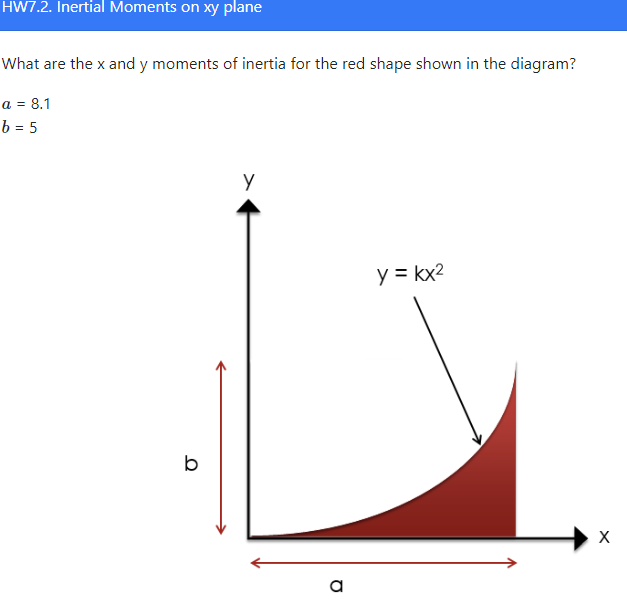

%% HW7.2  Inertial Moments on xy plane
%% Y = KX^2
%% Moment 计算需要记住 Ix = y^2*dA
a = 8.1; % 
b = 5.0; % 
k=b/a^2;

syms x y;
I1=int(y^2*(a-sqrt(y/k)),y,0,b);
I2=int(x^2*k*x^2,x,0,a);
vpa([I1,I2])

$$ans = \left(\begin{array}{cc} 48.214285714285714285714285714286 & 531.441 \end{array}\right)$$

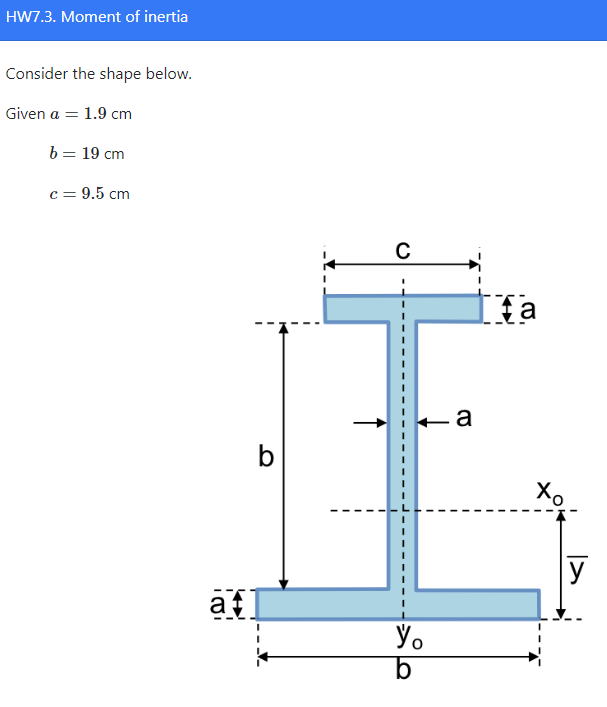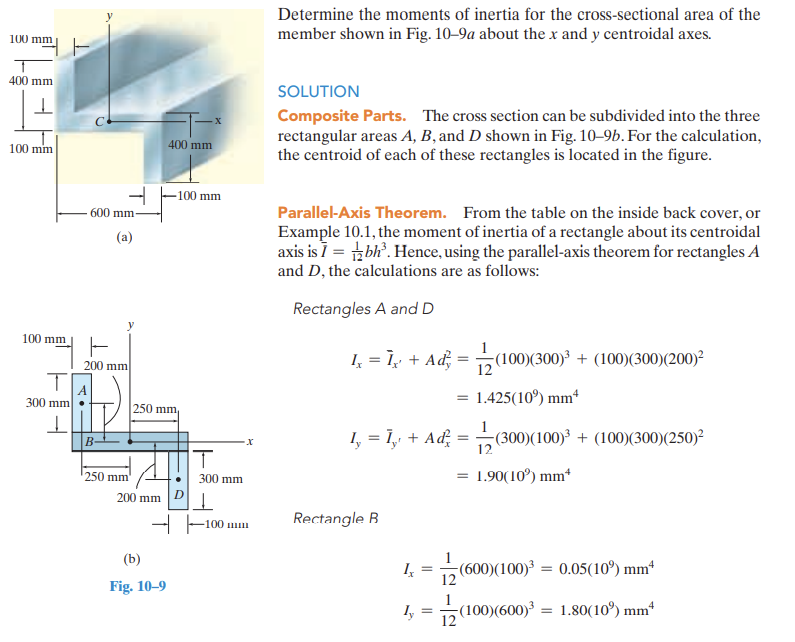

%% HW7.3 Moment of inertia

a = 1.9; % cm
b = 19.0; % cm
c = 9.5; % cm
%% 先算出yave 及该物体的重心 然后积分 也可以用定理 公式中 dx是重心之间的距离
%% 矩形: Ix = bh^3/12   计算Ix b就是和x轴平行的边！！！
%% 圆:   Ix = pi*r^4/4   
A=a*b+a*b+a*c;
yave=(a*b*0.5*a+b*a*(b/2+a)+a*c*(a+b+1/2*a))/A;
syms	x	y;
% Ix=vpa(int(y^2*b,y,-yave,-yave+a)+int(y^2*a,y,-yave+a,-yave+a+b)+int(y^2*c,y,-yave+a+b,-yave+a+b+a))
I1 = b*a^3/12 + a*b*(yave-a/2)^2;
I2 = c*a^3/12 + a*c*(yave-a-b-a/2)^2;
I3 = a*b^3/12 + a*b*(yave-a-b/2)^2;
Ixx = vpa(I1+I2+I3)

$$Ixx = 6621.3928083333339600358158349991$$


I4 = a*b^3/12;
I5 = a*c^3/12;
I6 = b*a^3/12;
Iyy = vpa(I4 + I5 + I6)

$$Iyy = 1232.6194583333331138419453054667$$

%% Iy=vpa(int(x^2*a,x,-b/2,b/2)+int(x^2*b,x,-a/2,a/2)+int(x^2*a,x,-c/2,c/2))

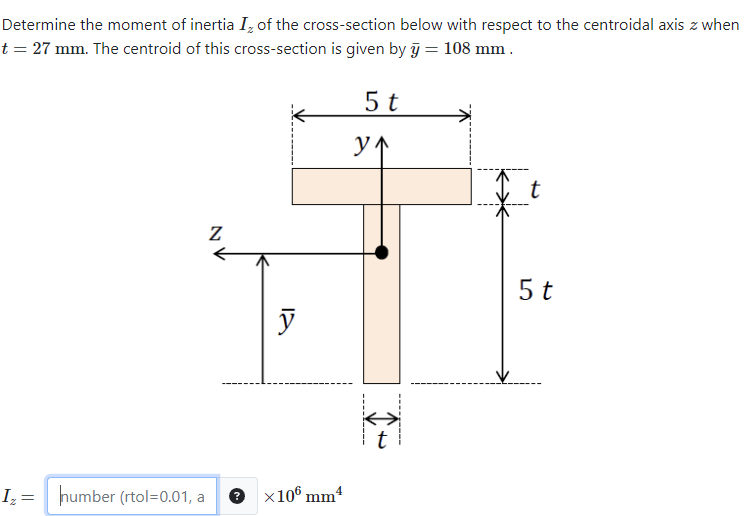

%% HW7.4. Find centroid composite cross section
t = 27;
y_a = 108;
%% 继续用定理 
I1 = t*(5*t)^3/12 + 5*t^2*abs(y_a-5/2*t)^2;
I2 = 5*t*(t)^3/12 + 5*t^2*abs(y_a-5.5*t)^2;
Iz = vpa(I1 + I2)

$$Iz = 17714700.0$$

Izz = Iz/10^6

$$Izz = 17.7147$$

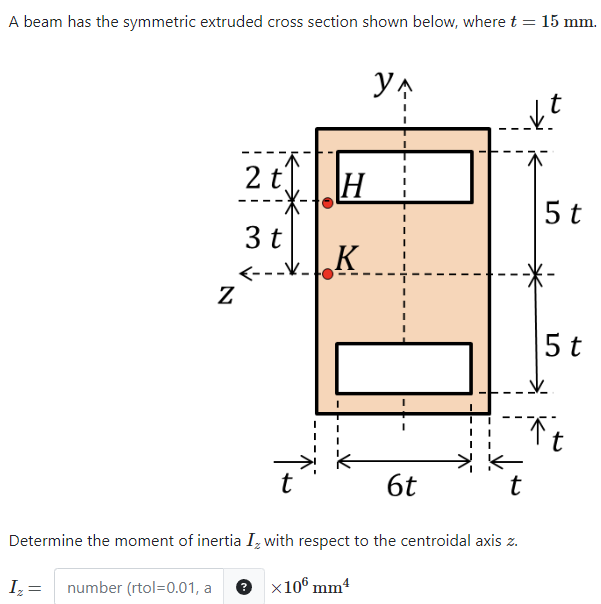

%% HW7.5. Determine the moment of inertia

t = 15;
I1 = 6*t*(2*t)^3/12+ 2*t*6*t*(4*t)^2;
I2 = 8*t*(12*t)^3/12;
Iz = vpa(I2-2*I1)

$$Iz = 38475000.0$$

Iz = Iz/10^6

$$Iz = 38.475$$

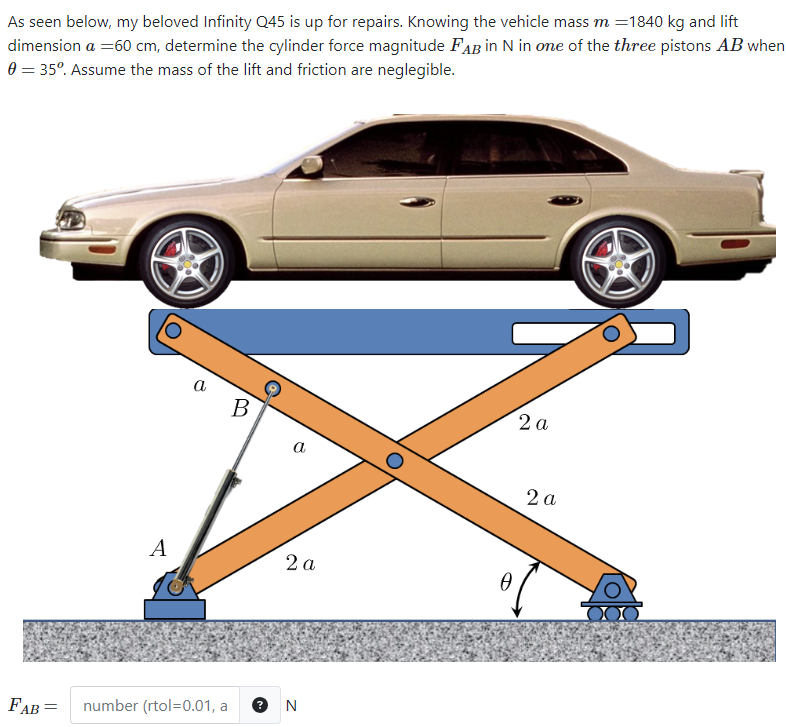

%% HW7.6. A little hard virtual work problem

a = 0.6;
m = 1840;
theta = 35;

w = m * 9.81;
syms va t;
ab = sqrt(5*va^2-4*va^2*cos(2*t))

$$ab = \sqrt{5\,{\mathrm{va}}^{2}-4\,{\mathrm{va}}^{2}\,\cos\left(2\,t\right)}$$

dab = diff(ab,t)

$$dab = \frac{4\,{\mathrm{va}}^{2}\,\sin\left(2\,t\right)}{\sqrt{5\,{\mathrm{va}}^{2}-4\,{\mathrm{va}}^{2}\,\cos\left(2\,t\right)}}$$

dab = subs(fn,[va,t],[a,theta*[pi/180]]);
dab = vpa(dab)

$$dab = 1.1833928897148154723330374631462$$

dh = 4*a*cosd(theta);
%% dab = 4*a*sind(2*theta)/sqrt(5-4*cosd(2*theta))
%% 题目里说了有三根
Fab = vpa(dh*w/dab)/3

$$Fab = 9995.6808520607452188757258501031$$

%% HW7.7. Virtual work - conceptual

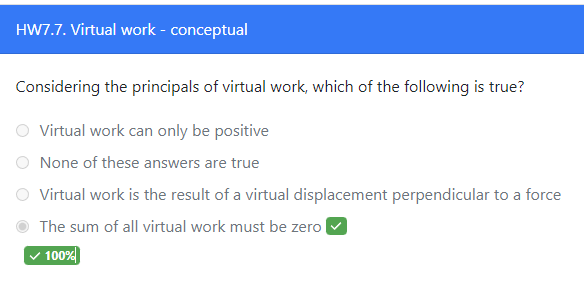

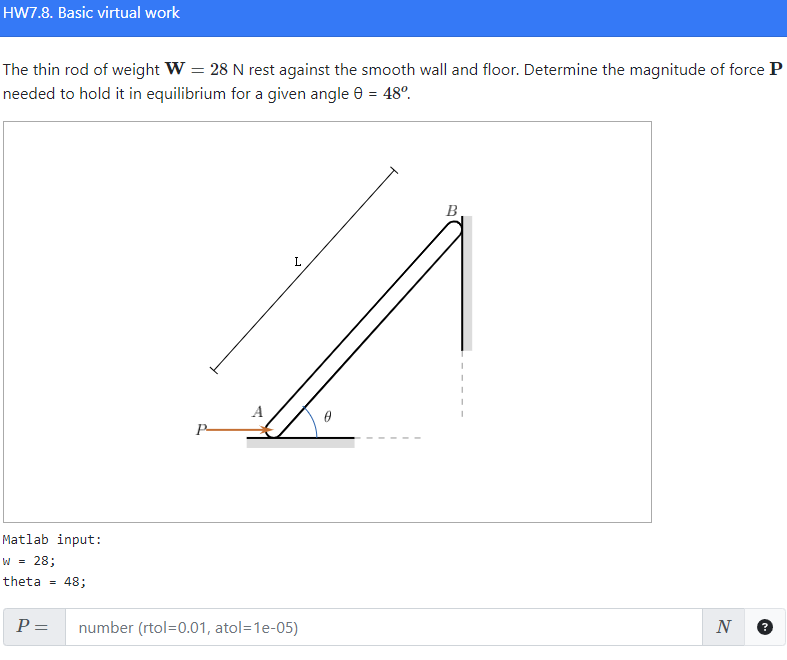

%% HW7.8. Basic virtual work

w = 28; 
theta = 48;
Fb=w*cosd(theta)/2/sind(theta);
P=Fb

P = 12.6057

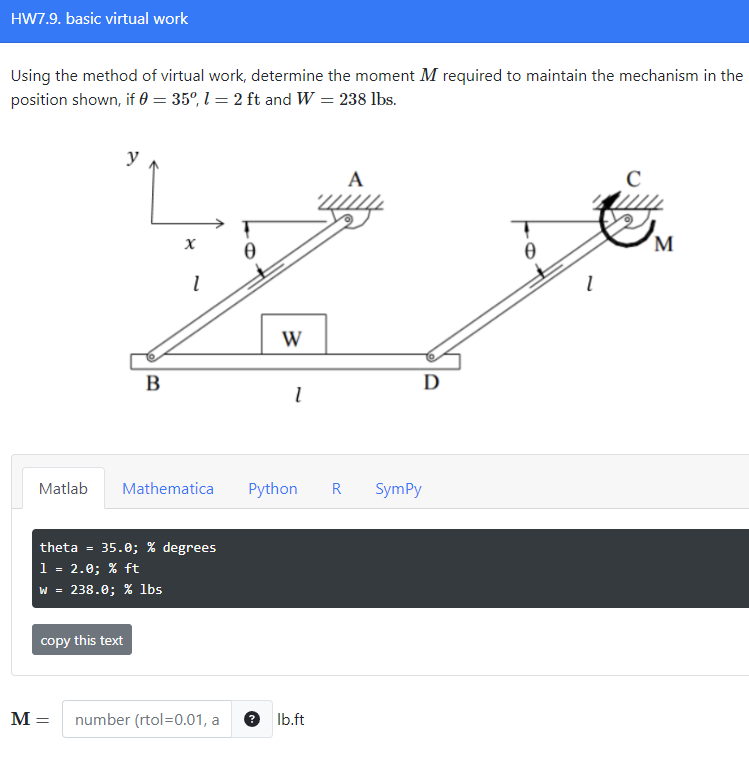

%% HW7.9. basic virtual work

theta = 35.0; % degrees
l = 2.0; % ft
w = 231.0; % lbs

M = w*l*cosd(theta)

M = 378.4482